## Connect to Arduino and collect data

clear device
device = serialport("/dev/cu.usbmodem1101",115200);
configureTerminator(device,"CR/LF");
Ts = 0.01; % s
testDuration = 40; % s

serialData = strings((testDuration/Ts),1);

for i = 1:(testDuration/Ts)
    serialData(i) = readline(device);
end


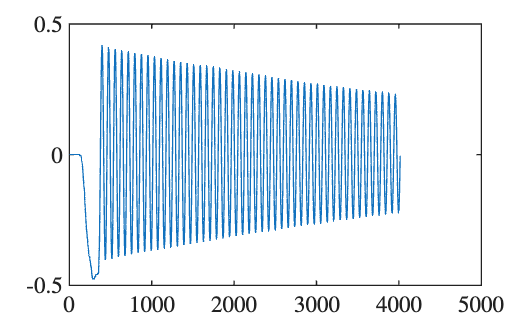

rawData = NaN((testDuration/Ts),2);

for i = 1:(testDuration/Ts)
    rawData(i,:) = reshape(str2double(split(serialData(i),',')), 1,2);
end

rawData(:,1) = rawData(:,1)/1000;

[resampledData, t] = resample(rawData(:,2)*(pi()/180), rawData(:,1)-rawData(1:1), 1/(Ts), "spline");  % Resample data to ensure consistent fixed timesteps
resampledData = [resampledData t];

plot(resampledData(:,1))


clear serialData i testDuration device t

## Trim the data & setup ID data

plot(resampledData(:,1))

Ts = 0.01;
% using data closer to the end of the test to have lower angular velocities
% and therefore less compunding of non-linear damping
startIndex = 3227; % x=1938, y=1946, z=3223
endIndex = 4015; % x=2582, y=2649, z=4010

if (endIndex<0)
    y = resampledData(startIndex:end,1);
    tVec = resampledData(startIndex:end,2) - resampledData(startIndex,2);
else
    y = resampledData(startIndex:endIndex,1);
    tVec = resampledData(startIndex:endIndex,2) - resampledData(startIndex,2);
end

data = iddata(y,[],Ts,"Name","SwingTest");

Unrecognized function or variable 'y'.

data.OutputName = "theta";
data.OutputUnit = "rad";
data.Tstart = 0;
data.TimeUnit = 's';
  
plot(tVec, y)

## Parameter setup

g = 9.81;
I_cfRod = (1/2)*0.0211*(0.01^2 + 0.012^2); % (1/2)*m*(r1^2 + r2^2)

CAD_I_gsmm = 3280586.05; 
% x=1630296.24, y=2155583.48 , z=3280586.05
CAD_I = CAD_I_gsmm*(10^-9);

m = 0.645;
l = 0.10345; 

I_tot_init = CAD_I;
c_init = 0.0003;
c_bearing_init = 0;

## Manual Calculations (MC)

MC_theta0 = -0.0129252;
MC_dtheta0 = 2.15;

n = 10;
magnitude_1 = 0.261;
magnitude_n = 0.232;
tau = 0.7875;


delta = (1/n)*log(magnitude_1/magnitude_n);
zeta = delta/(sqrt(4*pi()^2 + delta^2));
omega_n = (2*pi())/(tau*sqrt(1-zeta^2));

MC_I_tot = ((m*g*l*tau^2*(1-(zeta^2)))/(4*pi()^2));
% MC_I_tot = CAD_I + m*l^2 + I_cfRod;
format long; MC_I = MC_I_tot - m*l^2 - I_cfRod

MC_I =      3.512737554295536e-04


format bank; MC_I_gsmm = MC_I*10^9

MC_I_gsmm =      351273.76


MC_percDiff = 100*(MC_I-CAD_I)/CAD_I

MC_percDiff =           8.52



MC_c = 2*(MC_I_tot)*zeta*(2*pi())/(tau*sqrt(1-zeta^2));

MC_sys = idgrey('linear_greybox_ss', {m, g, l, MC_I_tot, MC_c}, 'c');

% [MC_y_initial, MC_t_initial] = initial(MC_sys, [MC_theta0 MC_dtheta0], linspace(0, tVec(end), 100000));
% figure, clf, hold on
% plot(MC_t_initial, MC_y_initial)
% plot(tVec, y)
% hold off

[~,MC_fit,~] = compare(MC_sys, data);

Unrecognized function or variable 'data'.

compare(MC_sys, data)


## Linear state-space (LSS) greybox estimation

LSS_sys = idgrey('linear_greybox_ss', {m, g, l, I_tot_init, c_init}, 'c');
LSS_sys.Structure.Parameters(1).Free = false;
LSS_sys.Structure.Parameters(2).Free = false;
LSS_sys.Structure.Parameters(3).Free = false;
LSS_sys.Structure.Parameters(4).Minimum = 0;
LSS_sys.Structure.Parameters(5).Minimum = 0;
LSS_sys.StateName = {'theta'; 'dtheta'};
LSS_sys.OutputName = {'theta'};
LSS_sys.OutputUnit = 'rad';

opts = greyestOptions('InitialState','estimate', 'SearchMethod', 'lsqnonlin');
opts.SearchOptions.StepTolerance = 1e-9;
opts.SearchOptions.FunctionTolerance = 1e-9;
opts.SearchOptions.MaxIterations = 4000;
opts.SearchOptions.Advanced.MaxFunEvals = 40000;

[LSS_sys_est, x0] = greyest(data,LSS_sys,opts);

format short
LSS_WhyStop = LSS_sys_est.Report.Termination.WhyStop

LSS_WhyStop = 'Change in cost was less than the specified tolerance.'

LSS_Iterations = LSS_sys_est.Report.Termination.Iterations

LSS_Iterations = 1278

LSS_fit = LSS_sys_est.Report.Fit.FitPercent

LSS_fit = 97.8651


LSS_theta0 = x0(1);
LSS_dtheta0 = x0(2);

LSS_I_tot = LSS_sys_est.Structure.Parameters(4).Value;
format long; LSS_I = LSS_I_tot - m*l^2 - I_cfRod

LSS_I =    0.003379394084627


format bank; LSS_I_gsmm = LSS_I*10^9

LSS_I_gsmm =     3379394.08


LSS_percDiff = 100*(LSS_I-CAD_I)/CAD_I

LSS_percDiff =           3.01


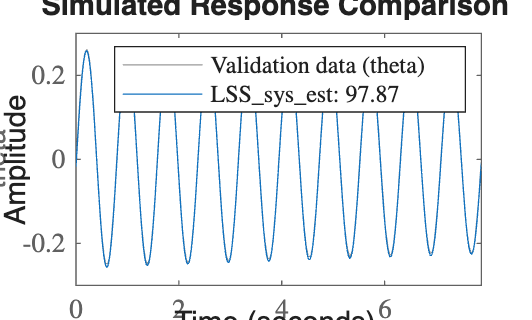


format long; LSS_c = LSS_sys_est.Structure.Parameters(5).Value;

% [LSS_y_initial, LSS_t_initial] = initial(LSS_sys, [LSS_theta0 LSS_dtheta0], tVec(end));
% figure, clf, hold on
% plot(LSS_t_initial, LSS_y_initial)
% plot(tVec, y)
% hold off

compare(LSS_sys_est, data)

## Non-linear state-space (NLSS) greybox estimation

NLSS_sys = idnlgrey('nl_greybox_ss', [1 0 2], {I_tot_init, c_init, c_bearing_init, m, g, l});
NLSS_sys.Parameters(1).Minimum = 0;            % Limit I to positive
NLSS_sys.Parameters(2).Minimum = 0;            % Limit c to positive
NLSS_sys.Parameters(3).Fixed = true;           % Fix c_bearing
NLSS_sys.Parameters(4).Fixed = true;           % fix m
NLSS_sys.Parameters(5).Fixed = true;           % fix g
NLSS_sys.Parameters(6).Fixed = true;           % fix l
NLSS_sys.InitialStates(1).Fixed = false;       % estimate theta(0)
NLSS_sys.InitialStates(2).Fixed = false;       % estimate dtheta(0)

opts = nlgreyestOptions('SearchMethod', 'lsqnonlin');
opts.SearchOptions.StepTolerance = 1e-9;
opts.SearchOptions.FunctionTolerance = 1e-9;
opts.SearchOptions.MaxIterations = 4000;
opts.SearchOptions.Advanced.MaxFunEvals = 40000;

NLSS_sys_est = nlgreyest(data,NLSS_sys,opts);

format short
NLSS_WhyStop = NLSS_sys_est.Report.Termination.WhyStop

NLSS_WhyStop = 'Change in cost was less than the specified tolerance.'

NLSS_Iterations = NLSS_sys_est.Report.Termination.Iterations

NLSS_Iterations = 1152

NLSS_fit = NLSS_sys_est.Report.Fit.FitPercent;

NLSS_theta0 = NLSS_sys_est.InitialStates(1).Value

NLSS_theta0 = -0.0161

NLSS_dtheta0 = NLSS_sys_est.InitialStates(2).Value

NLSS_dtheta0 = 2.0648


NLSS_I_tot = NLSS_sys_est.Parameters(1).Value;
format long; NLSS_I = NLSS_I_tot - m*l^2 - I_cfRod

NLSS_I =    0.003304230154255


format bank; NLSS_I_gsmm = NLSS_I*10^9

NLSS_I_gsmm =     3304230.15


NLSS_percDiff = 100*(NLSS_I-CAD_I)/CAD_I

NLSS_percDiff =           0.72


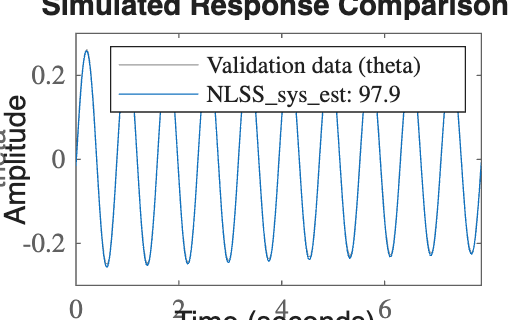


format long; NLSS_c = NLSS_sys_est.Parameters(2).Value;
NLSS_c_bearing = NLSS_sys_est.Parameters(3).Value/10000000;

% [NLSS_y_initial, NLSS_t_initial] = initial(NLSS_sys, [NLSS_theta0 NLSS_dtheta0], tVec(end));
% figure, clf, hold on
% plot(NLSS_t_initial, NLSS_y_initial)
% plot(tVec, y)
% hold off

compare(NLSS_sys_est, data)

## Comparison

Methods = ["ManualCalc"; "LSS"; "NLSS"; "CAD"];
I = [MC_I_gsmm; LSS_I_gsmm; NLSS_I_gsmm; CAD_I_gsmm];
percDiff = [MC_percDiff; LSS_percDiff; NLSS_percDiff; 0];
fit = [MC_fit; LSS_fit; NLSS_fit; 0];
c = [MC_c; LSS_c; NLSS_c; 0];
theta0 = [MC_theta0; LSS_theta0; NLSS_theta0; 0];
dtheta0 = [MC_dtheta0; LSS_dtheta0; NLSS_dtheta0; 0];

format short;
interest = table(Methods, I, percDiff, fit, c, theta0, dtheta0);
disp(interest)

      Methods           I         percDiff     fit          c          theta0      dtheta0
    ____________    __________    ________    ______    __________    _________    _______

    "ManualCalc"    3.3772e+06     2.9452     97.755    0.00030758    -0.012925      2.15 
    "LSS"           3.3794e+06     3.0119     97.865    0.00036828    -0.017427    2.0632 
    "NLSS"          3.3042e+06    0.72073     97.902    0.00036382    -0.016102    2.0648 
    "CAD"           3.2806e+06          0          0             0            0         0 



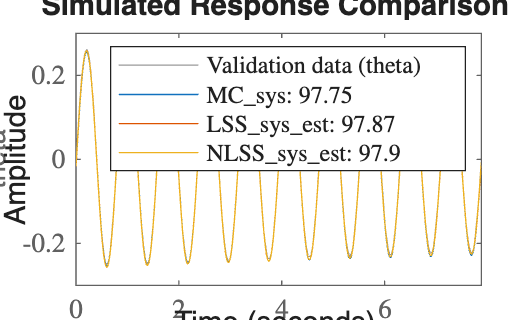


compare(MC_sys, LSS_sys_est, NLSS_sys_est, data)


clearvars -except resampledData Ts startIndex endIndex CAD_I_gsmm m l I_tot_init c_init c_bearing_init MC_theta0 MC_dtheta0 n magnitude_1 magnitude_n tau